clc; clear; close all; addpath(fullfile('z_toolbox'));
addpath(fullfile('z_toolbox', 'Violinplot'));
subG = {'sub-0001', 'sub-0002', 'sub-0003', 'sub-0004', 'sub-0005', ...
        'sub-0007', 'sub-0008', 'sub-0009', 'sub-0010', 'sub-0011', ...
        'sub-0012', 'sub-0013', 'sub-0014', 'sub-0015', 'sub-0016', ...
        'sub-0017', 'sub-0019', 'sub-0020', 'sub-0021', 'sub-0022', ...
        'sub-0023', 'sub-0028', 'sub-0029', 'sub-0031', 'sub-0033', ...
        'sub-0034', 'sub-0035', 'sub-0036', 'sub-0039', 'sub-0046', ...
        'sub-0047', 'sub-0050', 'sub-0052', 'sub-0054', 'sub-0062', ...
        'sub-0063', 'sub-0066', 'sub-0067', 'sub-0074', 'sub-0077', ...
        'sub-0087', 'sub-0089', 'sub-0092', 'sub-0093', 'sub-0094', ...
        'sub-0113', 'sub-0115'};
DSIpath = fullfile('step2_fiberTrack', 'DSI');
N = 0;
for nS = 1:length(subG)
    subID = subG{nS};
    qaDir = dir(fullfile(DSIpath, subID, [subID, '_ses-001_run-001_space-ACPC_desc-preproc_dwi_Yeo2011_7Networks_qa.mat']));
    if length(qaDir) == 1
        N = N + 1;
        load(fullfile(qaDir(1).folder, qaDir(1).name));
        qaYeo7_es = connectivity;
        qaYeo7_es(qaYeo7_es==0) = nan;
        qaYeo7_as(:,:,N) = qaYeo7_es; 
        load(fullfile(qaDir(1).folder, [subID, '_ses-001_run-001_space-ACPC_desc-preproc_dwi_Yeo2011_7Networks_meanlength.mat']));
        mlYeo7_es = connectivity;
        mlYeo7_es(mlYeo7_es==0) = nan;
        mlYeo7_as(:, :, N) = mlYeo7_es;
    end
end
MASK = qaYeo7_as;
MASK(~isnan(MASK)) = 1;
MASK = sum(MASK, 3, 'omitnan');
MASK(MASK<11) = nan;
MASK(~isnan(MASK)) = 1;
qaYeo7_DSI = mean(qaYeo7_as, 3, 'omitnan');
mlYeo7_DSI = mean(mlYeo7_as, 3, 'omitnan');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ml = mlYeo7_DSI;  qa = qaYeo7_DSI;
ml = triu(ml); idx = find(ml>0);
ml = ml(idx);  qa = qa(idx);
[r, p] = corr(ml, qa, 'type', 'Spearman');
disp(['r = ', num2str(r), ' p = ', num2str(p)]);

r = 0.58006 p = 0


figure('Units', 'centimeters', 'Position', [5, 5, 36, 30]);
subplot(3, 3, 1);
scatter(ml, qa, 'filled', 'MarkerFaceColor', [0.5, 0.5, 0.5]); 
hold on;
[~, Curve, ~] = f_polyfit(ml, qa, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlabel('SC Length (mm)'); ylabel('SC QA');
xlim([min(ml), max(ml)]); ylim([min(qa), max(qa)]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qa = qaYeo7_DSI; ml = mlYeo7_DSI;
load(fullfile('step7_IEDtw_Yeo7', 'IEDtw_delays_rate_Yeo7_51ROIs.mat'));
Mask = IEDtwD_Yeo7_51ROIs_as_mean.*qa;
idx = find(Mask>0);
qa = qa(idx); ml = ml(idx); IEDtwD = IEDtwD_Yeo7_51ROIs_as_mean(idx);
v = ml./IEDtwD;
idx = find(v > (mean(v)-3*std(v)) & v < (mean(v) + 3*std(v)));
qa = qa(idx); v = v(idx);
[r, p] = corr(qa, v, 'Type', 'Spearman');
disp(['r = ', num2str(r), ' p = ', num2str(p)]);

r = 0.45006 p = 1.3461e-49


subplot(3, 3, 2);
scatter(qa, v, 'filled', 'MarkerFaceColor', [0.5, 0.5, 0.5]); 
hold on;
[~, Curve, ~] = f_polyfit(qa, v, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlabel('SC QA'); ylabel('IED-TW Velocity (mm/ms)');
xlim([min(qa), max(qa)]); ylim([min(v), 7]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qa = qaYeo7_DSI; ml = mlYeo7_DSI;
load(fullfile('step7_IEDtw_Yeo7', 'NAxc_delays_strength_Yeo7_51ROIs.mat'));
Mask = NAxcD_Yeo7_51ROIs_as_mean.*qa;
idx = find(Mask>0);
qa = qa(idx); ml = ml(idx); NAtwD = NAxcD_Yeo7_51ROIs_as_mean(idx);
v = ml./NAtwD;
idx = find(v > (mean(v)-3*std(v)) & v < (mean(v) + 3*std(v)));
qa = qa(idx); v = v(idx);
[r, p] = corr(qa, v, 'Type', 'Spearman');
disp(['r = ', num2str(r), ' p = ', num2str(p)]);

r = 0.62174 p = 1.8128e-105


subplot(3, 3, 3);
scatter(qa, v, 'filled', 'MarkerFaceColor', [0.5, 0.5, 0.5]); 
hold on;
[~, Curve, ~] = f_polyfit(qa, v, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlabel('SC QA'); ylabel('NA-LC Velocity (mm/ms)');
xlim([min(qa), max(qa)]); ylim([min(v), max(v)]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## DMI from HCP

clc; clear;
load(fullfile('step2_fiberTrack', 'whole_brain_Yeo2011_7Networks_meanlength.mat'));
ml = connectivity;
load(fullfile('step2_fiberTrack', 'whole_brain_Yeo2011_7Networks_qa.mat'));
qa = connectivity; 
idx = find(ml~=0); ml = ml(idx);  qa = qa(idx);
subplot(3, 3, 4);
scatter(ml, qa, 'filled', 'MarkerFaceColor', [0, 0, 0]); 
hold on;
[~, Curve, ~] = f_polyfit(ml, qa, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlabel('SC Length (mm)');
ylabel('SC QA');
xlim([min(ml), max(ml)]);
ylim([min(qa), max(qa)]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
[r, p] = corr(ml, qa, 'type', 'Spearman');
disp(['r = ', num2str(r), ' p = ', num2str(p)]);

r = 0.65423 p = 1.7194e-95


## Fiber qa vs. IED conduction velocity

clc; clear;
load(fullfile('step2_fiberTrack', 'whole_brain_Yeo2011_7Networks_meanlength.mat'));
ml = connectivity;
load(fullfile('step2_fiberTrack', 'whole_brain_Yeo2011_7Networks_qa.mat'));
qa = connectivity;
load(fullfile('step7_IEDtw_Yeo7', 'IEDtw_delays_rate_Yeo7_51ROIs.mat'));
Mask = IEDtwR_Yeo7_51ROIs_as_mean;
Mask(ml==0) = nan; Mask(qa==0) = nan; 
IEDtwD = IEDtwD_Yeo7_51ROIs_as_mean(~isnan(Mask));
ml = ml(~isnan(Mask)); 
v = ml./IEDtwD;
qa = qa(~isnan(Mask));
idx = find(v<(mean(v)+ 3*std(v)) & v > (mean(v) - 3*std(v)));
v = v(idx); 
qa = qa(idx);
subplot(3, 3, 5);
scatter(qa, v, 'filled', 'MarkerFaceColor', [0, 0, 0]); 
hold on;
[~, Curve, ~] = f_polyfit(qa, v, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlabel('SC QA'); ylabel('IED-TW Velocity (mm/ms)');
xlim([min(qa), max(qa)]);
ylim([min(v), max(v)]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
[r, p] = corr(qa, v, 'type', 'Spearman');
disp(['r=', num2str(r), ' p=', num2str(p)]);

r=0.55343 p=4.2004e-42


## SC QA VS NA XC velocity

clc; clear;
load(fullfile('step2_fiberTrack', 'whole_brain_Yeo2011_7Networks_meanlength.mat'));
ml = connectivity;
load(fullfile('step2_fiberTrack', 'whole_brain_Yeo2011_7Networks_qa.mat'));
qa = connectivity;
load(fullfile('step7_IEDtw_Yeo7', 'NAxc_delays_strength_Yeo7_51ROIs.mat'));
Mask = NAxcD_Yeo7_51ROIs_as_mean;
Mask(ml==0) = nan; 
Mask(qa==0) = nan; 
Mask(ml==0) = nan;
NAxcD = NAxcD_Yeo7_51ROIs_as_mean(~isnan(Mask));
ml = ml(~isnan(Mask));
v = ml./NAxcD;
qa = qa(~isnan(Mask));
idx = find(v<(mean(v)+ 3*std(v)) & v > (mean(v) - 3*std(v)));
v = v(idx); qa = qa(idx);
[r, p] = corr(qa, v, 'type', 'Spearman');
disp(['r=', num2str(r), ' p=', num2str(p)]);

r=0.67046 p=5.4969e-68


subplot(3, 3, 6);
scatter(qa, v, 'filled', 'MarkerFaceColor', [0, 0, 0]); hold on;
[~, Curve, ~] = f_polyfit(qa, v, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlabel('SC QA'); ylabel('NA-LC Velocity (mm/ms)');
xlim([min(qa), max(qa)]); ylim([min(v), max(v)]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## subject level analysis

% Calculate the relationship between IED TW velocity and fiber QA
clc; clear;
subG = {'sub-0001', 'sub-0002', 'sub-0003', 'sub-0004', 'sub-0005', ...
        'sub-0007', 'sub-0008', 'sub-0009', 'sub-0010', 'sub-0011', ...
        'sub-0012', 'sub-0013', 'sub-0014', 'sub-0015', 'sub-0016', ...
        'sub-0017', 'sub-0019', 'sub-0020', 'sub-0021', 'sub-0022', ...
        'sub-0023', 'sub-0028', 'sub-0029', 'sub-0031', 'sub-0033', ...
        'sub-0034', 'sub-0035', 'sub-0036', 'sub-0039', 'sub-0046', ...
        'sub-0047', 'sub-0050', 'sub-0052', 'sub-0054', 'sub-0062', ...
        'sub-0063', 'sub-0066', 'sub-0067', 'sub-0074', 'sub-0077', ...
        'sub-0087', 'sub-0089', 'sub-0092', 'sub-0093', 'sub-0094', ...
        'sub-0113', 'sub-0115'};
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
load(fullfile('step2_fiberTrack', 'FiberMatrix_ncount_length_qa_allsubject.mat'));
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_xcorr100ms_Rmax_delay_allSubject.mat'));
% ===== Main Processing Loop ======
N = 0;
for nS = 1:length(subG)
    subID = subG{nS};
    IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
    IEDtwR = IEDtw(nS).indirectTransferRateMatrix;
    NAxcD = Delay_allSubject{nS};
    NAxcR = xcR_allSubject{nS};
    currFiberLength = fiberLength{nS};
    currFiberqa = fiberqa{nS};
    if ~isempty(currFiberLength)
        N = N + 1;
        idx = find(currFiberLength>0);
        ml = currFiberLength(idx);
        qa = currFiberqa(idx);
        [r_ml_qa(N, 1), p_ml_qa(N, 1)] = corr(ml, qa, 'type', 'Spearman');
        % Mask 
        Mask = IEDtwR;
        Mask = Mask - diag(diag(Mask));
        Mask(isnan(Mask)) = 0;
        Mask(Mask < 0.1) = 0;
        Mask(currFiberLength == 0) = 0;
        Mask(IEDtwD == 0) = 0;
        % comvert matrix to series
        t = IEDtwD(Mask > 0);
        ml = currFiberLength(Mask > 0);
        v = ml./t;
        qa = currFiberqa(Mask>0);
        % remove outliers
        vUpper = mean(v) + 3*std(v);
        vLower = mean(v) - 3*std(v);
        idx = find(v > vLower & v < vUpper);
        v = v(idx); qa = qa(idx);
        % correlation analysis
        [r_qa_IEDv(N, 1), p_qa_IEDv(N, 1)] = corr(qa, v, 'type', 'Spearman');
        % Mask 
        Mask = NAxcR;
        Mask = Mask - diag(diag(Mask));
        Mask(isnan(Mask)) = 0;
        zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
        Mask(isnan(NAxcR) | isinf(NAxcR) | NAxcR <= zThd) = 0;
        Mask(isnan(NAxcD) | isinf(NAxcD) | NAxcD == 0) = 0;
        Mask(currFiberLength == 0) = 0;
        % comvert matrix to series
        t = NAxcD(Mask > 0);
        ml = currFiberLength(Mask > 0);
        v = ml./t;
        qa = currFiberqa(Mask>0);
        % remove outliers
        vUpper = mean(v) + 3*std(v);
        vLower = mean(v) - 3*std(v);
        idx = find(v > vLower & v < vUpper);
        v = v(idx); qa = qa(idx);
        % correlation analysis
        [r_qa_NAv(N, 1), p_qa_NAv(N, 1)] = corr(qa, v, 'type', 'Spearman');
    end
end
% ==== Violin Plot Visualization ====
for n = 1:length(r_ml_qa)
    groupStr1{n, 1} = 'SC Length vs. SC QA';
end
for n = 1:length(r_qa_IEDv)
    groupStr2{n, 1} = 'SC QA vs. IED-TW Velocity';
end
for n = 1:length(r_qa_NAv)
    groupStr3{n, 1} = 'SC QA vs. NA-LC Velocity';
end
% Combine data and labels for plotting
SpearmanR = [r_ml_qa; r_qa_IEDv; r_qa_NAv];
disp(mean(r_ml_qa)); disp(std(r_ml_qa));

    0.6953

    0.1254



disp(mean(r_qa_IEDv)); disp(std(r_qa_IEDv));

    0.5177

    0.1468



disp(mean(r_qa_NAv)); disp(std(r_qa_NAv));

    0.4590

    0.1342



% Boef correction
p_ml_qa = p_ml_qa*length(p_ml_qa);
if max(p_ml_qa)<0.05; disp('significant');end

significant


p_qa_IEDv = p_qa_IEDv*length(p_qa_IEDv);
if max(p_qa_IEDv)<0.05; disp('significant');end

significant


p_qa_NAv = p_qa_NAv*length(p_qa_NAv);
if max(p_qa_NAv)<0.05
    disp('significant');
else
    disp(length(find(p_qa_NAv>0.05)));
end

     1



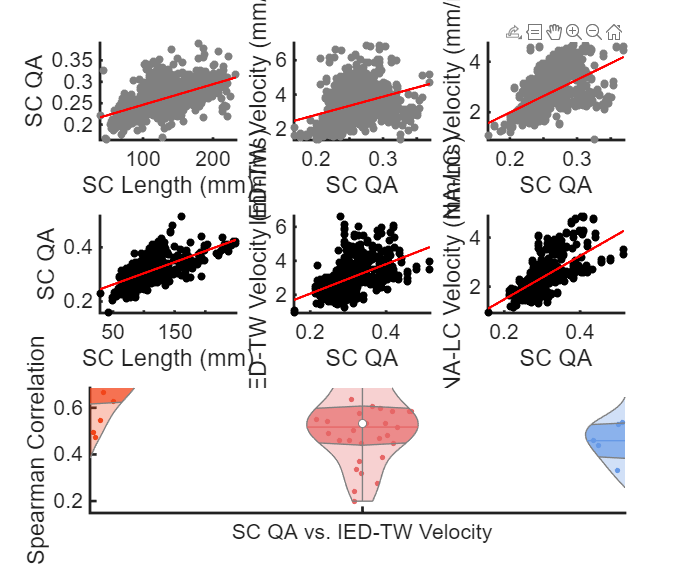

Origin = [groupStr1; groupStr2; groupStr3];
grouporder = {'SC Length vs. SC QA', ...
        'SC QA vs. IED-TW Velocity', ...
        'SC QA vs. NA-LC Velocity'};
% Violin plot
subplot(3, 3, [7, 8, 9]);
vs = violinplot(SpearmanR, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', grouporder, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.9, 0.4, 0.4; 0.4, 0.6, 0.9;], ...
    'ShowMean', true, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.3, 3.7]); ylim([0.05, 1]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);